# **Shape Deviation Analysis**

**This Workflow calculates the the area distortion, the mesh skew angle and the mesh anisotropy of a transformation mesh grid made with the Workflow_ReflectronCorrection_GridPointsExtraction all stored in one variable the meshDistortions**

Prerequisite - load intersection points

## Export mesh grid to .obj

the .obj file is stored in the current folder

sampleID = '4000XHR_Erlangen_4818_distortionMesh';
% triangulation of the intersection points
alpha = 10; % [mm] alpha value for triangulation
gridTris = alphaTriangulation(alphaShape(intersections.detectorX,intersections.detectorY, alpha));
% save for .obj
fv.faces = gridTris;
gridTrisVertices(:,3) = zeros(1,1)';
fv.vertices = gridTrisVertices;
objFileName = [sampleID '.obj']; 
patchToObj(fv,sampleID,objFileName);
 

## Blender

Import .obj file

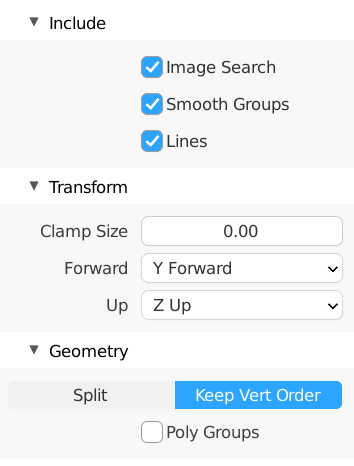

Go to Edit mode and edge selection 

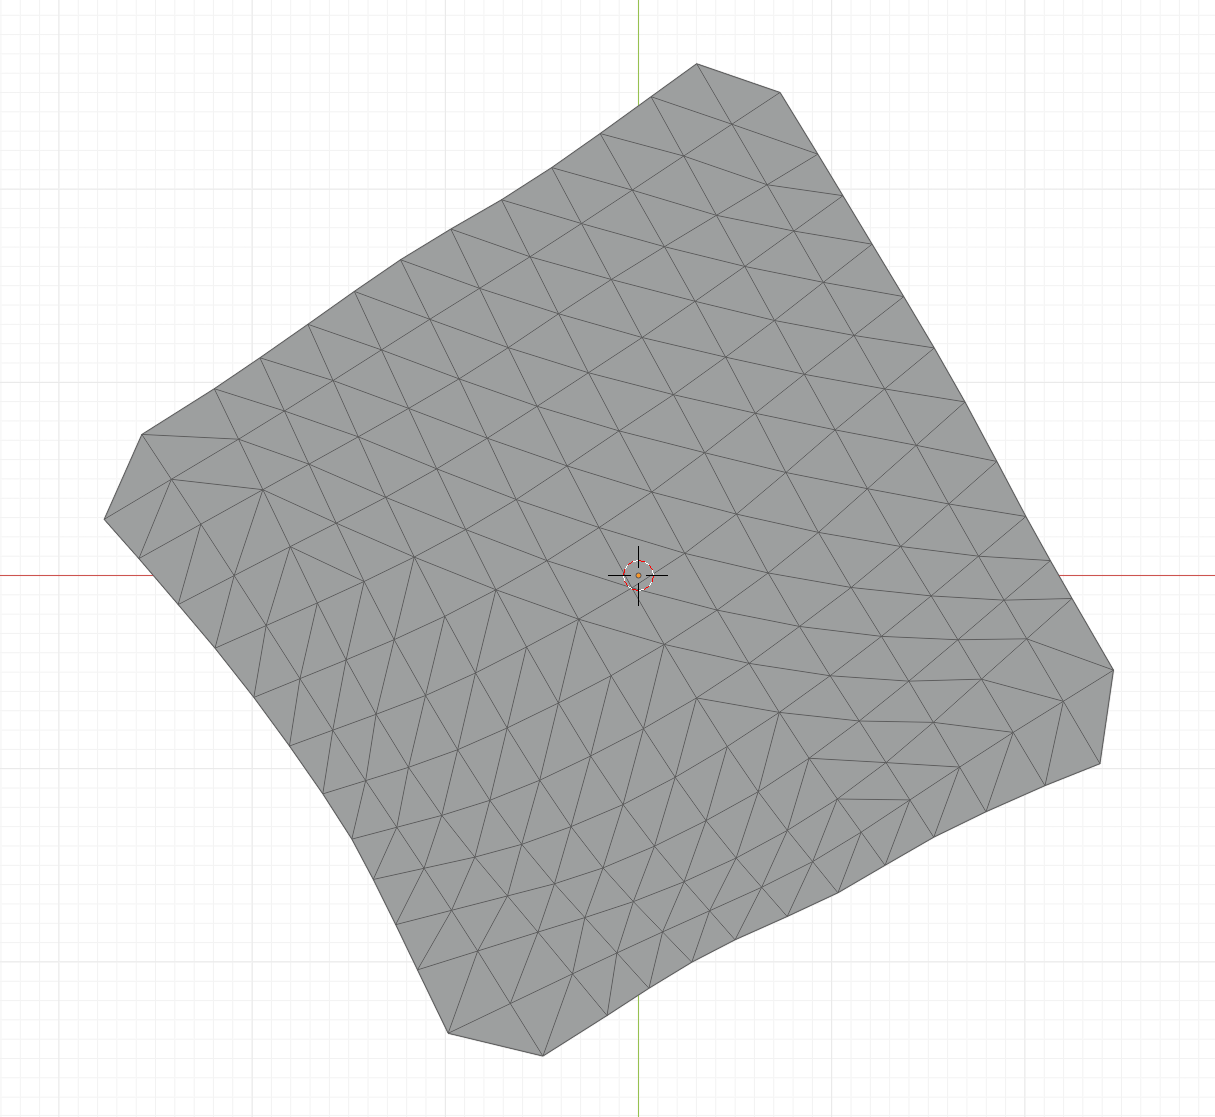

Delete the triangulation in edit Mode with 'C' and Mesh > delete > dissolve edges (deletes edges without deleting the face). 

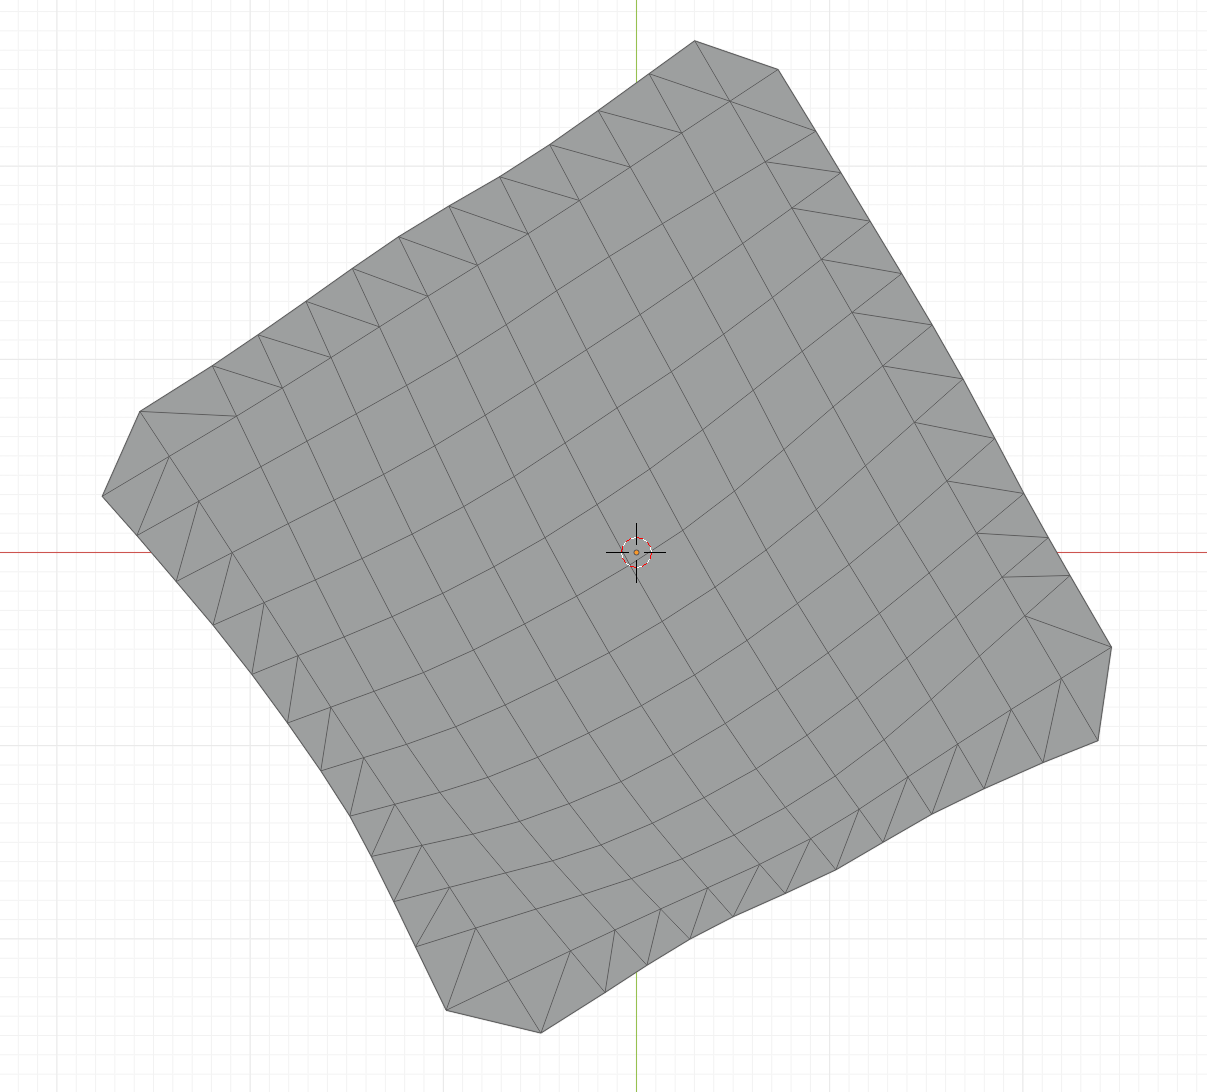

Afterwards delete the outer squares. 

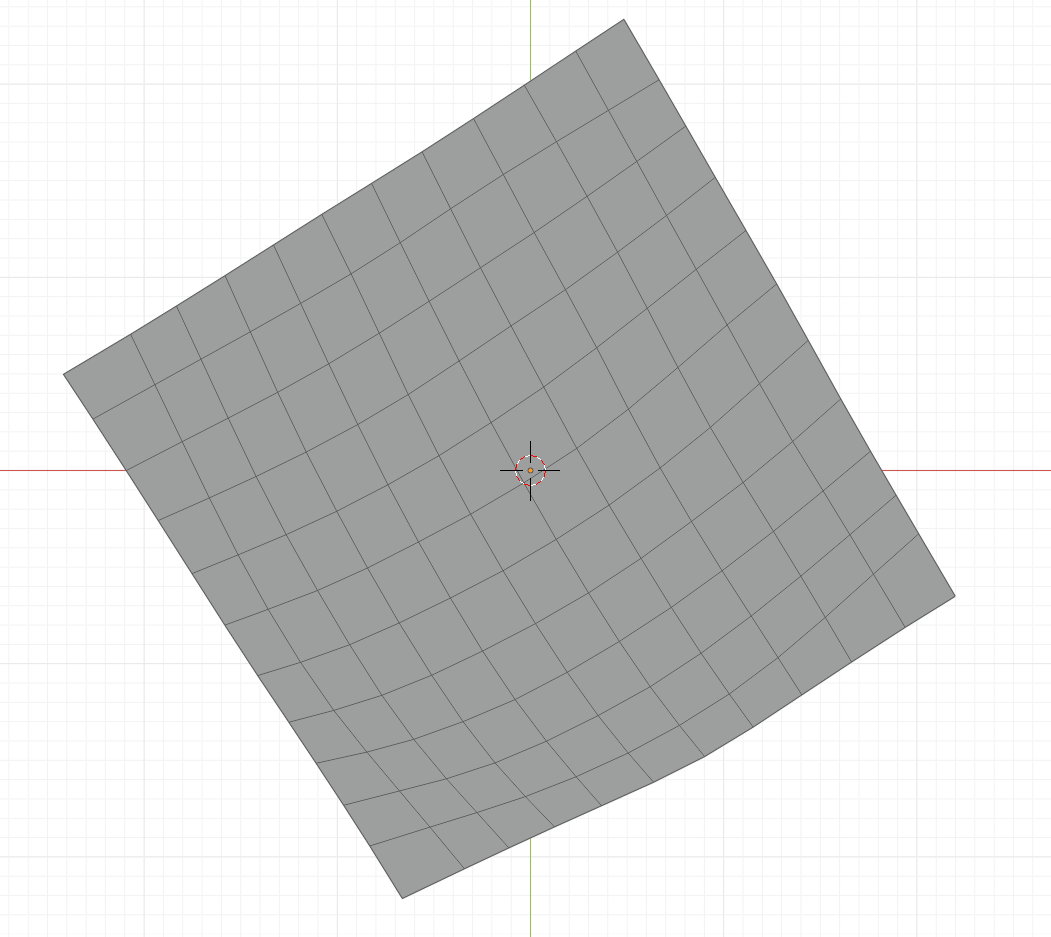

Export it as .obj 

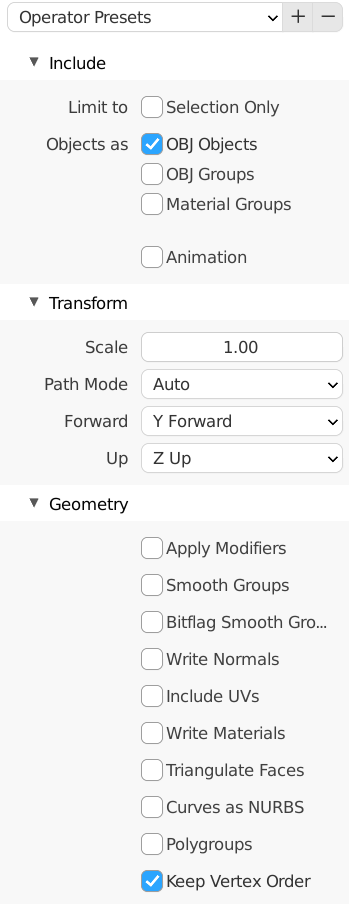

## Load the modified quadrilateral Mesh into Matlab

[objFile, objPath] = uigetfile({'*.obj'},'select obj file');
[obj, gr] = objToPatch([objPath objFile]);
fv.faces = obj.objects.faces;
fv.vertices = obj.vertices;
 

## Find distortion around each vertex and plot the mesh

figure;
patch(fv,'FaceColor',[1 0 1],'FaceAlpha',0.3);
for i=1:length(fv.vertices)
    text(fv.vertices(i,1)+.3,fv.vertices(i,2)-.3,fv.vertices(i,3),num2str(i));
end
axis equal
 

## Calculation of the mesh anisotropie, the mesh area and the mesh skew angle

% generate edge list (unique edges)
delAdjacencyIdx = [];
numQuad = length(fv.faces);
permut = [1,2; 2,3; 3,4; 4,1];
for perm = 1:4
    p = permut(perm,:);
    delAdjacencyIdx(numQuad*(perm-1)+1:numQuad*perm,:) = fv.faces(:,p);
end
delAdjacencyIdx = [delAdjacencyIdx; [delAdjacencyIdx(:,2) delAdjacencyIdx(:,1)]];
edgeList = delAdjacencyIdx;
[edgeList, ~, ~] = unique(edgeList,'rows');
edgeList = sort(edgeList,2);
[edgeList, idxa, idxb] = unique(edgeList,'rows');

% Calculate the mesh anisotropy
meshAnisotropy = zeros(max(max(edgeList)),1);
meshSkewAngle = zeros(max(max(edgeList)),1);
meshArea = zeros(max(max(edgeList)),1);

for v = 1:length(fv.vertices)
    % find neighboring vertices
    neighbors = edgeList(sum(edgeList == v,2) & not(edgeList == v));
    vec = zeros(length(neighbors),3);
 
    for e = 1:length(neighbors)
        vec(e,:) = fv.vertices(neighbors(e),:) - fv.vertices(v,:);
    end

    [B, idx] = sortrows(sign(vec),'descend');
    vec = vec(idx,:);

    meshAnisotropy(v,1) = NaN;
    meshSkewAngle(v,1) = NaN;
    meshArea(v,1) = NaN;

    switch length(neighbors)
        case 1
            error('mesh with stray vertices');

        case 2 
            % mesh corner

        case 3 
            % mesh edge

        case 4
            % mesh interior
            meshArea(v,1) = ...
                norm(cross(vec(1,:),vec(3,:))) + ...
                norm(cross(vec(3,:),vec(4,:))) + ...
                norm(cross(vec(4,:),vec(2,:))) + ...
                norm(cross(vec(2,:),vec(1,:)));
  
            meshSkewAngle(v,1) = ...
                90 - atan2d(norm(cross(vec(1,:),vec(3,:))),dot(vec(1,:),vec(3,:)));
            
            meshAnisotropy(v,1) = norm(vec(3,:) - vec(2,:)) / norm(vec(1,:) - vec(4,:));
    end

end

meshDistortions = table(meshAnisotropy, meshArea, meshSkewAngle, 'VariableNames',["meshAnisotropy", "meshArea", "meshSkewAngle" ] );
clearvars -except meshDistortions fv

 

## Plot the area distortion and save it in the current folder as .fig, .jpg and.tif

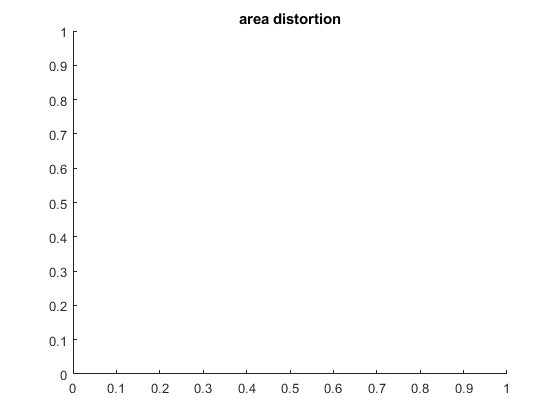

f = figure;
title 'area distortion'

patch('Faces',fv.faces,'Vertices',fv.vertices,...
    'FaceVertexCData',(meshDistortions.meshArea/mean(meshDistortions.meshArea(not(isnan(meshDistortions.meshArea))))-1) *100,'FaceColor','interp');

Unable to resolve the name fv.faces.

colorbar
colormap jet
hold on 
axis equal
% you can change size and position of the image here
rectangle('Position',[-15 -15 30 30],'Curvature',[1 1],'EdgeColor','b')
caxis([-30 20])
% saves images
savefig(f,[sampleID + '_areaDistortion']);
saveas(f,[sampleID + '_areaDistortion'],'jpg');
saveas(f,[sampleID + '_areaDistortion'],'tif');
 

## Plot the mesh skew angle

f = figure;
title 'mesh skew angle'
patch('Faces',fv.faces,'Vertices',fv.vertices,...
    'FaceVertexCData',meshDistortions.meshSkewAngle,'FaceColor','interp');
colormap jet
colorbar
hold on 
axis equal
rectangle('Position',[-15 -15 30 30],'Curvature',[1 1],'EdgeColor','b')
caxis([-15 15]);
% saves images
savefig(f,[sampleID + '_meshSkewAngle']);
saveas(f,[sampleID + '_meshSkewAngle'],'jpg');
saveas(f,[sampleID + '_meshSkewAngle'],'tif');
 

## Plot the mesh anisotropie

f = figure;
title 'mesh anisotropy'
patch('Faces',fv.faces,'Vertices',fv.vertices,...
    'FaceVertexCData',(meshDistortions.meshAnisotropy-1)*100,'FaceColor','interp');
colorbar
colormap jet
hold on 
axis equal
rectangle('Position',[-15 -15 30 30],'Curvature',[1 1],'EdgeColor','b')
caxis([-20 20]);
% saves images
savefig(f,[sampleID + '_meshAnisotropy']);
saveas(f,[sampleID + '_meshAnisotropy'],'jpg');
saveas(f,[sampleID + '_meshAnisotropy'],'tif');
 

## Save meshDistortions!